Difference between two images 

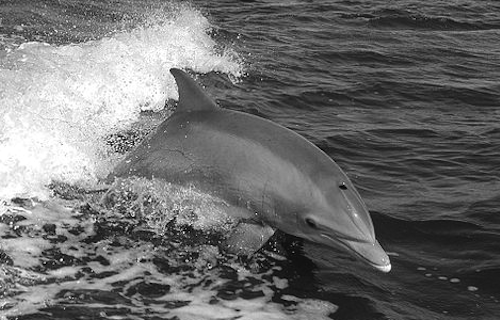 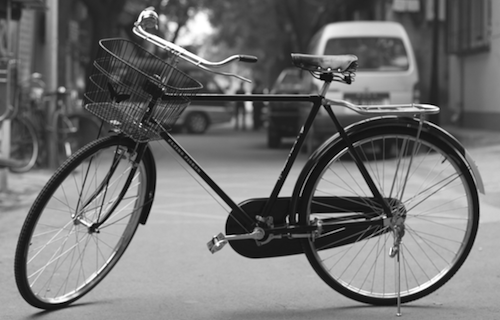

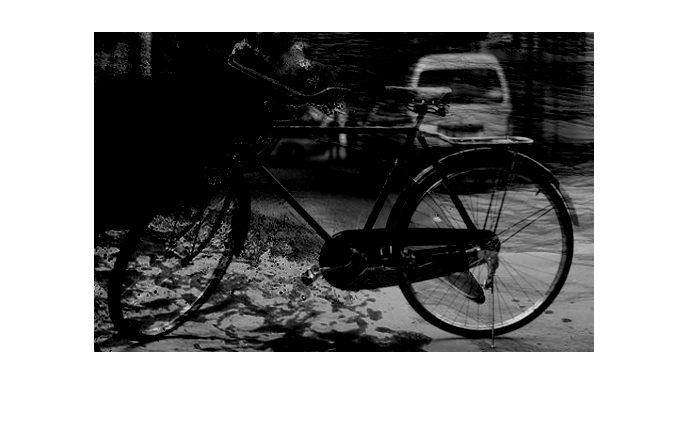

bicycle = imread("ud810\course_images\bicycle.png");
dolphin = imread("ud810\course_images\dolphin.png");
diff1 = bicycle - dolphin;
imshow(diff1);

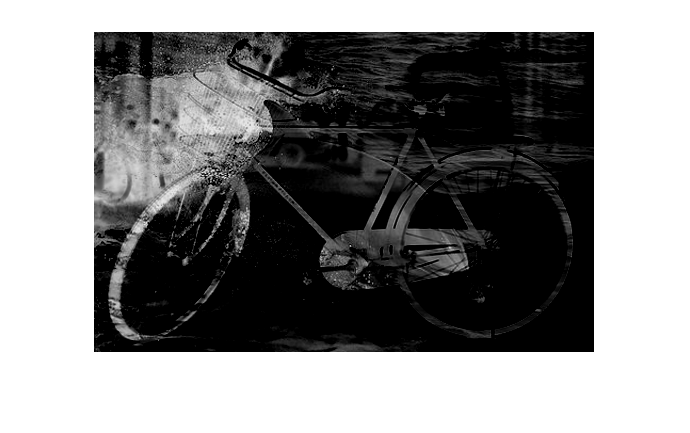

diff2 = dolphin - bicycle;
imshow(diff2);

diff3 = abs(bicycle - dolphin); 
imshow(diff3);

diff4 = (bicycle - dolphin) + (dolphin - bicycle)

diff4 = 320×500 uint8 matrix
   38   34   37   60   67   53   41   28   33   66   59   17   43   38   15    7   30   30   33   25    2    1    8    9    2    3    8   22   23    8   10   13   15   16   17   39   17    6   24   18   11   33   29    4    6   54   55   49   80   87
   46    1   22   18   38   37   37   24   10    7   31   54   48   36   19   23   42   44   14   26   30   31   19   23   26   19   10    5    7   12   20   25    2    0    5   31   19   18    1    0    8   11    3    0    9   10    6   38   65   62
   60   21   29    9   29   36   21   16   31   22    6   30   40   22   35   43   37   37   31   33   47   53   31   11    7    9   15   20    8    1   32   24   14   16   28   18    8   20   14   27   45   47   17   12    6   10    3   16   72   43
   27   10   21   25   32   29   43   46   27   23   42   37   16   28   41   57   37   38   49   43   40   39   33   37   30    9    6   19   13   10   23    3   14   27   27   11   34   43   19   31   40   35   21   

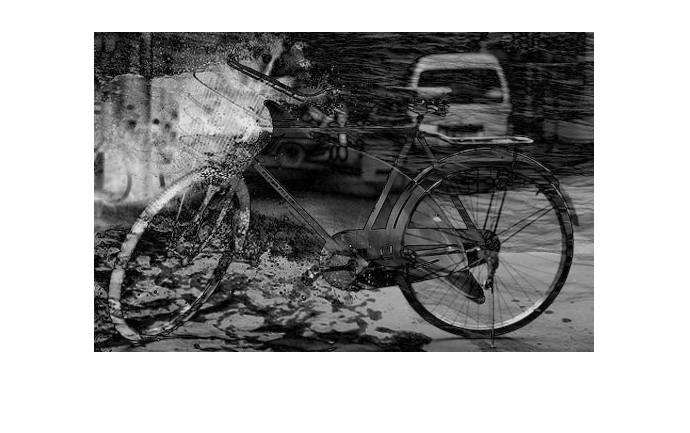

imshow(diff4);

diff5 = abs(double(bicycle) - double(dolphin))

diff5 =     38    34    37    60    67    53    41    28    33    66    59    17    43    38    15     7    30    30    33    25     2     1     8     9     2     3     8    22    23     8    10    13    15    16    17    39    17     6    24    18    11    33    29     4     6    54    55    49    80    87
    46     1    22    18    38    37    37    24    10     7    31    54    48    36    19    23    42    44    14    26    30    31    19    23    26    19    10     5     7    12    20    25     2     0     5    31    19    18     1     0     8    11     3     0     9    10     6    38    65    62
    60    21    29     9    29    36    21    16    31    22     6    30    40    22    35    43    37    37    31    33    47    53    31    11     7     9    15    20     8     1    32    24    14    16    28    18     8    20    14    27    45    47    17    12     6    10     3    16    72    43
    27    10    21    25    32    29    43    46    27    23    42    37    16    28    4

You could have converted the images to double to account for negative values to not wash away and used abs to get same matrix as diff4,  and then used imshow(im, []) instead

imshow display varies based on what data type is passed to it, eventhough diff4 and diff5 have the same values but since the datatype is different imshow is behaving differently.

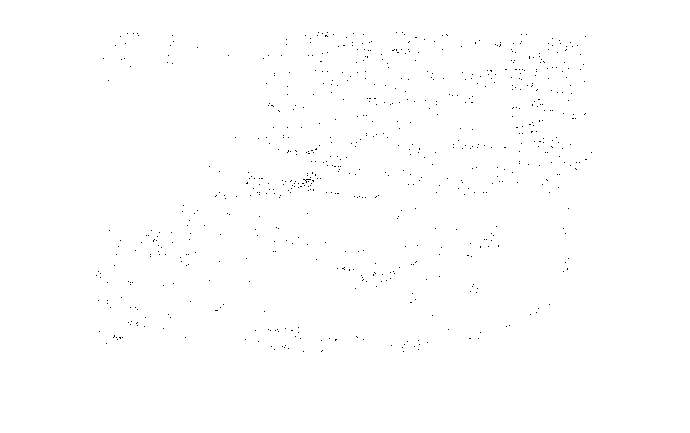

imshow(diff5);

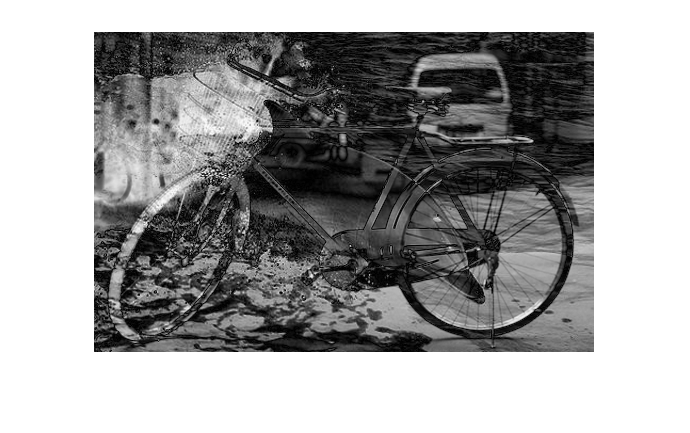

imshow(diff5,[]);